## E2

#### Gaussian

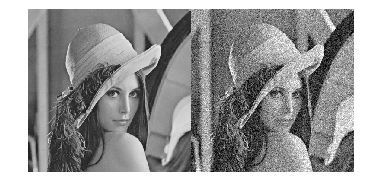

I = imread('lena_gray_512.tif');
J = imnoise(I,"gaussian",0,0.01);
montage({I,J});

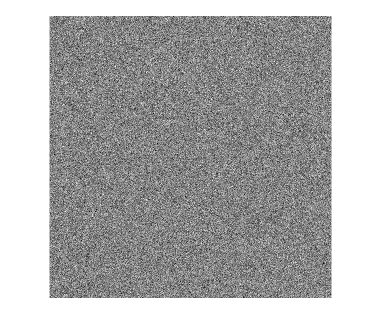

R = double(I) - double(J);
imshow(R,[]);

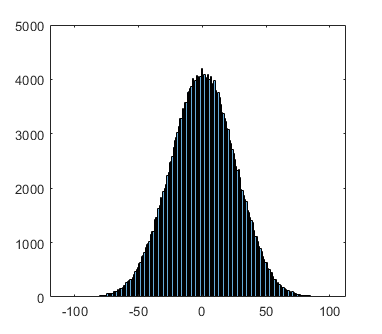

histogram(R);

#### Salt & pepper

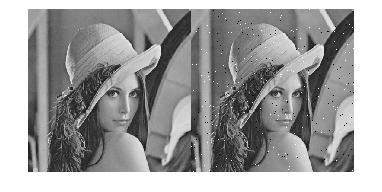

I = imread('lena_gray_512.tif');
J = imnoise(I,"salt & pepper",0.01);
montage({I,J});

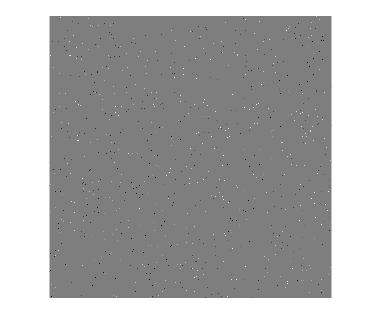

R = double(I) - double(J);
imshow(R,[]);

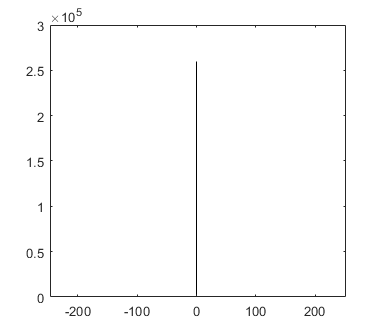

histogram(R);

#### Resize

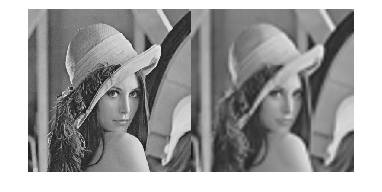

I = imread('lena_gray_512.tif');
J = imresize(I,[64 64]);
J = imresize(J,[512 512]);
montage({I,J});

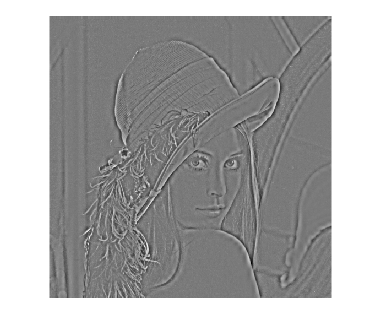

R = double(I) - double(J);
imshow(R,[]);

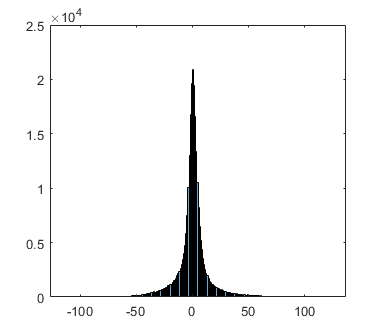

histogram(R);

## Processat de la imatge

#### Augmentar il·luminació

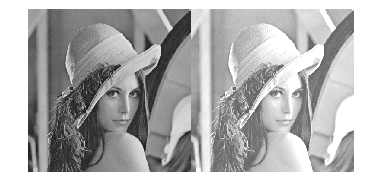

I = imread('lena_gray_512.tif');
J = I + 64; % il·luminació, però no augmenta el contrast
montage({I,J});

#### Invertir il·luminació

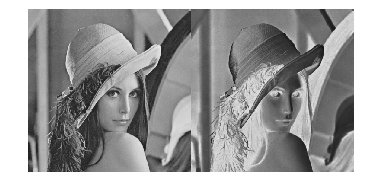

close all
I = imread('lena_gray_512.tif');
HI = imhist(I);
J = 255 - I; % invertir
HJ = imhist(J);
montage({I,J});

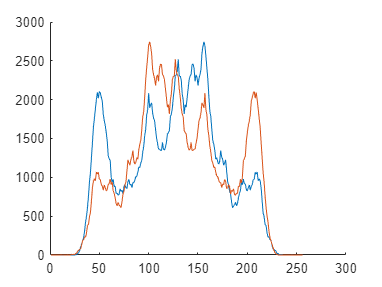

figure
hold on
plot(HI);
plot(HJ);

#### Reescalar

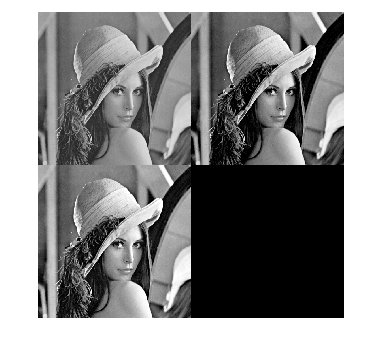

close all
I = imread('lena_gray_512.tif');
HI = imhist(I);
J = uint8(1.45*(I-50));
HJ = imhist(J);
Q = imadjust(I);
montage({I,J,Q});

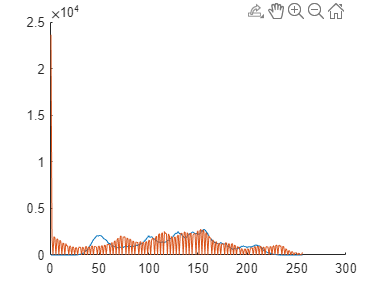

figure
hold on
plot(HI);
plot(HJ);

#### Equalització de l’histograma

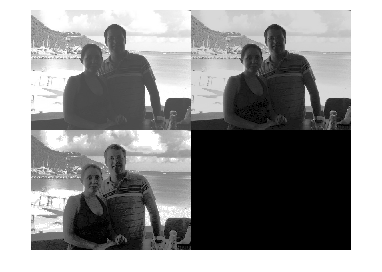

close all
I = rgb2gray(imread('bad_contrast.jpg'));
HI = imhist(I);
J = arrayfun(@myfunction2,I);
HJ = imhist(J);

Q = histeq(I);

montage({I,J,Q});

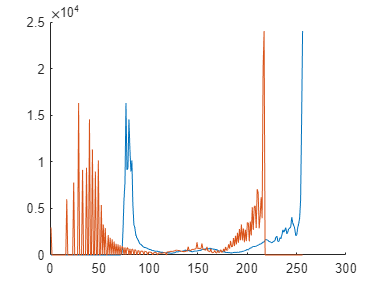

figure
hold on
plot(HI);
plot(HJ);

#### Transformacions a l'espai

hold off
I = imread("bigben.png");
imshow(I);
[x, y] = getpts

x =   380.0000
  379.0000
  405.0000
  401.0000


y =    165
   221
   248
   191


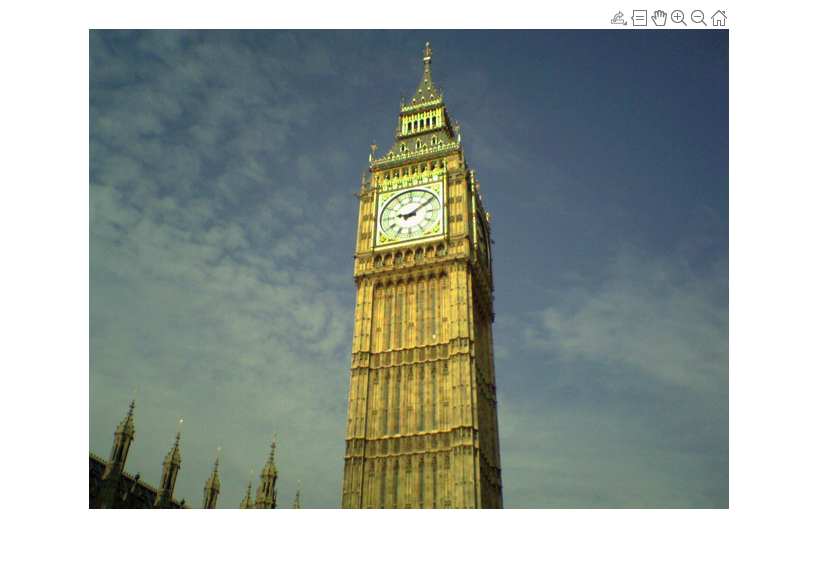

i =     5.0000
    9.0000
  626.0000
  624.0000


j =     9.0000
  466.0000
  472.0000
   21.0000


[i, j] = getpts

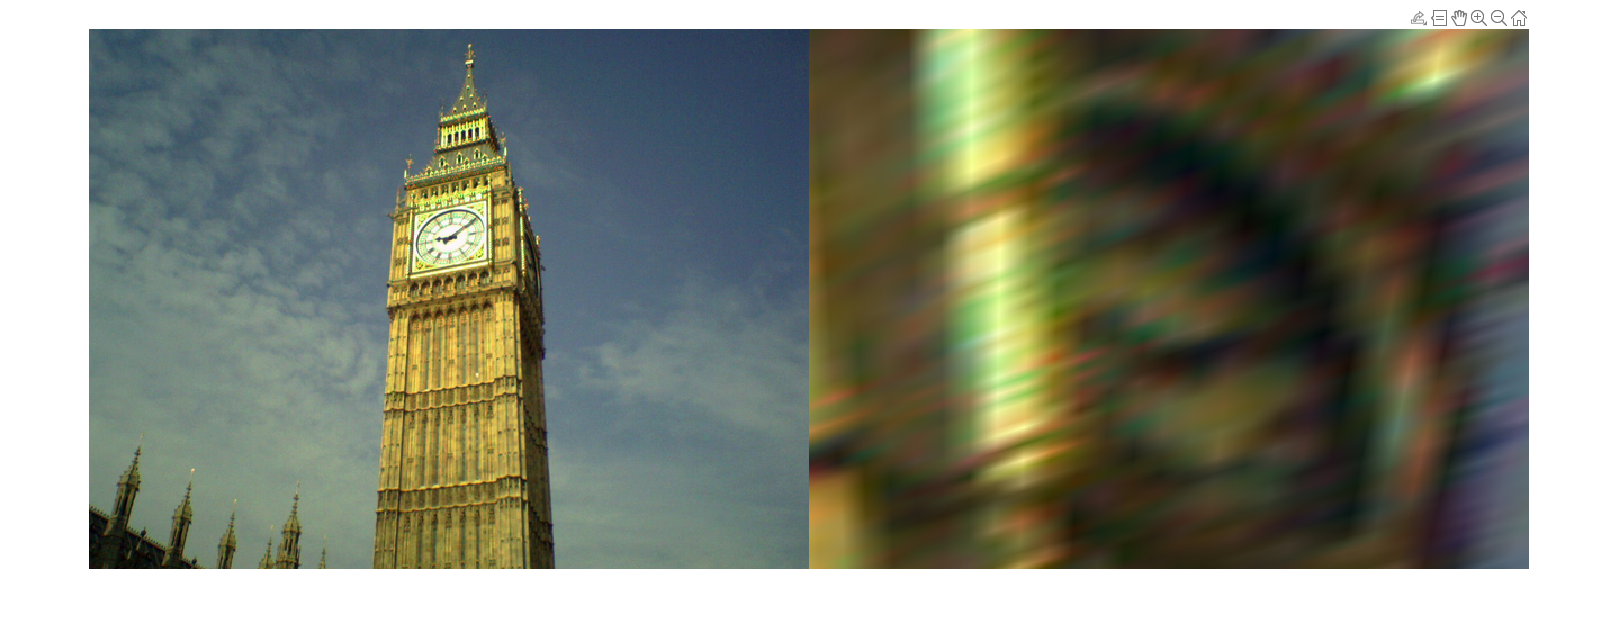

tform = fitgeotrans([x,y],[i,j],'projective');
J = imwarp(I,tform,'Outputview',imref2d(size(I)));
montage({I,J});